# Train DDPG Agent to Swing Up and Balance Pendulum

This example shows how to train a deep deterministic policy gradient (DDPG) agent to swing up and balance a pendulum modeled in Simulink®.

For more information on DDPG agents, see [Deep Deterministic Policy Gradient Agents](docid:rl_ug#mw_66c8fe60-f58e-4bdb-904a-21d442f0a879). For an example that trains a DDPG agent in MATLAB®, see [Train DDPG Agent to Control Double Integrator System](docid:rl_ug#mw_0b71212e-521a-4a57-bde7-5dde0c1e0c90).

## Pendulum Swing-Up Model

The reinforcement learning environment for this example is a simple frictionless pendulum that initially hangs in a downward position. The training goal is to make the pendulum stand upright without falling over using minimal control effort. 

Open the model.

mdl = "rlSimplePendulumModel";
% open_system(mdl)

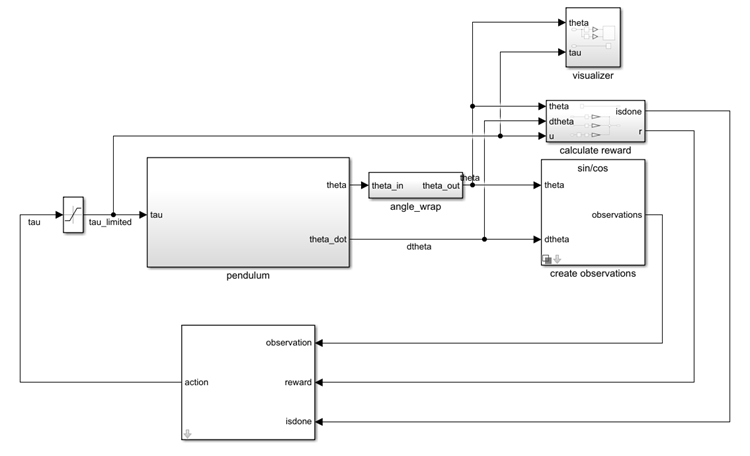

For this model:

- The upward balanced pendulum position is 0 radians, and the downward hanging position is `pi` radians.

- The torque action signal from the agent to the environment is from –2 to 2 N·m.

- The observations from the environment are the sine of the pendulum angle, the cosine of the pendulum angle, and the pendulum angle derivative.

- The reward $r_t$, provided at every time step, is


$$r_t =-\left({\theta_t }^2 +0\ldotp 1{\dot{\theta_t } }^2 +0\ldotp 001u_{t-1}^2 \right)$$


Here:

- $\theta_t$ is the angle of displacement from the upright position.

- $\dot{\theta_t }$ is the derivative of the displacement angle.

- $u_{t-1}$ is the control effort from the previous time step.

For more information on this model, see [Load Predefined Control System Environments](docid:rl_ug#mw_537f0c6d-2ccd-454b-95fa-3ee88ece74aa).

## Create Environment Interface

Create a predefined environment interface for the pendulum.

env = rlPredefinedEnv("SimplePendulumModel-Continuous")

env = <a href=""matlab: help rl.env.SimulinkEnvWithAgent"">SimulinkEnvWithAgent</a> with properties:

           Model : rlSimplePendulumModel
      AgentBlock : rlSimplePendulumModel/RL Agent
        ResetFcn : []
  UseFastRestart : on


obsInfo = getObservationInfo(env);

The interface has a continuous action space where the agent can apply torque values between –2 to 2 N·m to the pendulum.

actInfo = getActionInfo(env)

actInfo =   rlNumericSpec with properties:

     LowerLimit: -2
     UpperLimit: 2
           Name: "torque"
    Description: [0×0 string]
      Dimension: [1 1]
       DataType: "double"


Set the observations of the environment to be the sine of the pendulum angle, the cosine of the pendulum angle, and the pendulum angle derivative.

set_param( ...
    "rlSimplePendulumModel/create observations", ...
    "ThetaObservationHandling","sincos");

To define the initial condition of the pendulum as hanging downward, specify an environment reset function using an anonymous function handle. This reset function sets the model workspace variable `theta0` to `pi`.

env.ResetFcn = @(in)setVariable(in,"theta0",pi,"Workspace",mdl);

Specify the simulation time `Tf` and the agent sample time `Ts` in seconds.

Ts = 0.05;
Tf = 20;

Fix the random generator seed for reproducibility.

rng(0)

## Create DDPG Agent

DDPG agents use a parametrized Q-value function approximator to estimate the value of the policy. A Q-value function critic takes the current observation and an action as inputs and returns a single scalar as output (the estimated discounted cumulative long-term reward for which receives the action from the state corresponding to the current observation, and following the policy thereafter).

To model the parametrized Q-value function within the critic, use a neural network with two input layers (one for the observation channel, as specified by `obsInfo`, and the other for the action channel, as specified by `actInfo`) and one output layer (which returns the scalar value).

Define each network path as an array of layer objects and assign names to the input and output layers of each path. These names allow you to connect the paths and then later explicitly associate the network input and output layers with the appropriate environment channel.

For more information on creating a deep neural network value function representation, see [Create Policy and Value Function Representations](docid:rl_ug#mw_2c7e8669-1e91-4d42-afa6-674009a08004).

% Define state path.
statePath = [
    featureInputLayer( ...
        obsInfo.Dimension(1), ...
        Name="obsPathInputLayer")
    fullyConnectedLayer(400)
    reluLayer
    fullyConnectedLayer(300,Name="spOutLayer")
    ];

% Define action path.
actionPath = [
    featureInputLayer( ...
        actInfo.Dimension(1), ...
        Name="actPathInputLayer")
    fullyConnectedLayer(300, ...
        Name="apOutLayer", ...
        BiasLearnRateFactor=0)
    ];

% Define common path.
commonPath = [
    additionLayer(2,Name="add")
    reluLayer
    fullyConnectedLayer(1)
    ];

Create `dlnetwork` object, add layers and connect them.

criticNetwork = dlnetwork();
criticNetwork = addLayers(criticNetwork,statePath);
criticNetwork = addLayers(criticNetwork,actionPath);
criticNetwork = addLayers(criticNetwork,commonPath);
criticNetwork = connectLayers(criticNetwork,"spOutLayer","add/in1");
criticNetwork = connectLayers(criticNetwork,"apOutLayer","add/in2");

View the critic network configuration.

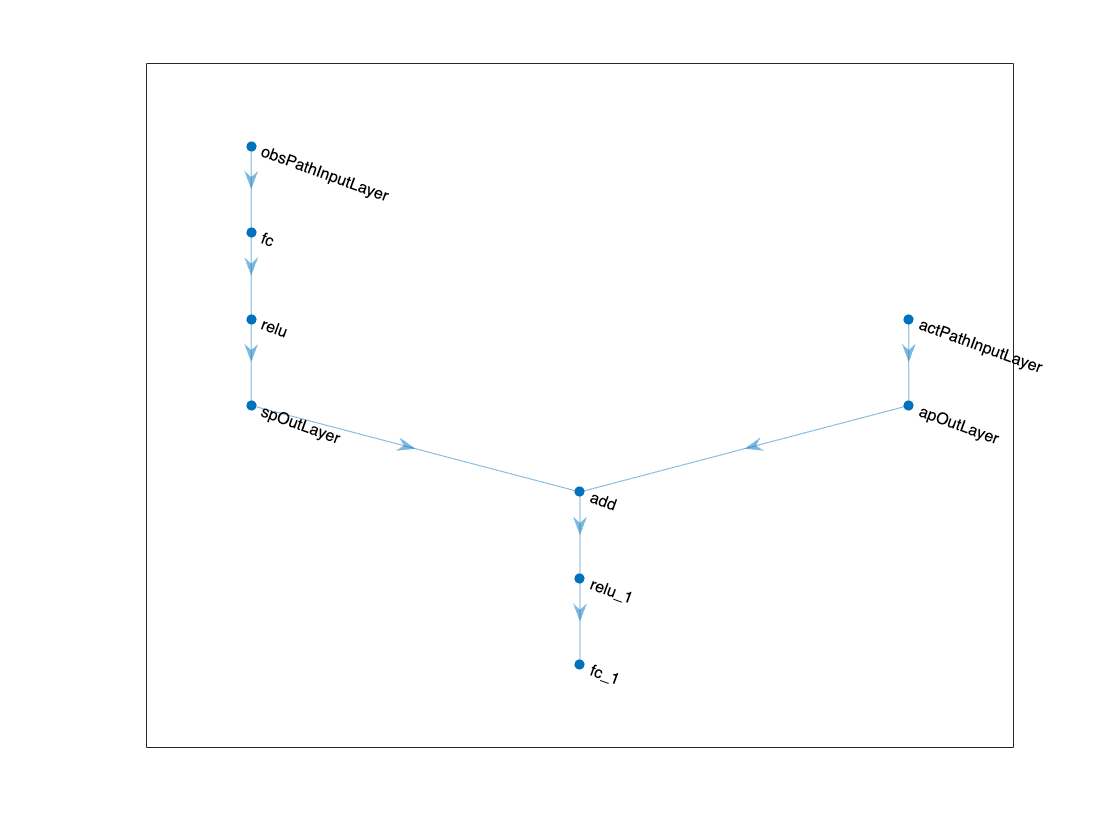

plot(criticNetwork)

Initialize network and display the number of weights.

criticNetwork = initialize(criticNetwork);
summary(criticNetwork)

   Initialized: true

   Number of learnables: 122.8k

   Inputs:
      1   'obsPathInputLayer'   3 features
      2   'actPathInputLayer'   1 features



Create the critic approximator object using `criticNet`, the environment observation and action specifications, and the names of the network input layers to be connected with the environment observation and action channels. For more information, see [`rlQValueFunction`](docid:rl_ref#mw_e6e7abac-0a33-423b-8473-1409879db701).

critic = rlQValueFunction(criticNetwork, ...
    obsInfo,actInfo, ...
    ObservationInputNames="obsPathInputLayer", ...
    ActionInputNames="actPathInputLayer");

DDPG agents use a parametrized deterministic policy over continuous action spaces, which is learned by a continuous deterministic actor.

A continuous deterministic actor implements a parametrized deterministic policy for a continuous action space. This actor takes the current observation as input and returns as output an action that is a deterministic function of the observation. 

To model the parametrized policy within the actor, use a neural network with one input layer (which receives the content of the environment observation channel, as specified by `obsInfo`) and one output layer (which returns the action to the environment action channel, as specified by `actInfo`).

Define the network as an array of layer objects. Since the output of the hyperbolic tangent layer is always between -1 and 1, use a scaling layer to scale it to the actual range of the action, as specified by `actInfo.UpperLimit`.

actorNetwork = [
    featureInputLayer(obsInfo.Dimension(1))
    fullyConnectedLayer(400)
    reluLayer
    fullyConnectedLayer(300)
    reluLayer
    fullyConnectedLayer(1)
    tanhLayer
    scalingLayer(Scale=max(actInfo.UpperLimit))
    ];

Convert to `dlnetwork`, initialize network and display the number of weights.

actorNetwork = dlnetwork(actorNetwork);
actorNetwork = initialize(actorNetwork);
summary(actorNetwork)

   Initialized: true

   Number of learnables: 122.2k

   Inputs:
      1   'input'   3 features



Create the actor using `actorNet` and the observation and action specifications. For more information on continuous deterministic actors, see [`rlContinuousDeterministicActor`](docid:rl_ref#mw_c2909424-90f4-4a52-803b-73310483e6c3).

actor = rlContinuousDeterministicActor(actorNetwork,obsInfo,actInfo);

Specify options for the critic and actor using [`rlOptimizerOptions`](docid:rl_ref#mw_18a712bb-b821-4dd9-a7ad-460ad7f2aa03).

criticOpts = rlOptimizerOptions(LearnRate=1e-03,GradientThreshold=1);
actorOpts = rlOptimizerOptions(LearnRate=1e-03,GradientThreshold=1);

Specify the DDPG agent options using [`rlDDPGAgentOptions`](docid:rl_ref#mw_5e9a4c5d-03d5-48d9-a85b-3c2d25fde43c), include the training options for the actor and critic.

agentOpts = rlDDPGAgentOptions(...
    SampleTime=Ts,...
    CriticOptimizerOptions=criticOpts,...
    ActorOptimizerOptions=actorOpts,...
    ExperienceBufferLength=1e5,...
    DiscountFactor=0.99,...
    MiniBatchSize=128);

You can also modify the agent options using dot notation.

agentOpts.NoiseOptions.StandardDeviation = 0.6;

Alternatively, you can create the agent first, and then access its option object and modify the options using dot notation.

Create the DDPG agent using the specified actor, critic, and agent options objects. For more information, see [`rlDDPGAgent`](docid:rl_ref#mw_7e49ed9c-eea8-4994-8532-c7f66d5359ef).

agent = rlDDPGAgent(actor,critic,agentOpts);

## Train Agent

To train the agent, first specify the training options. For this example, use the following options.

- Run training for at most 5000 episodes, with each episode lasting at most `ceil(Tf/Ts)` time steps.

- Display the training progress in the Reinforcement Learning Training Monitor dialog box (set the `Plots` option) and disable the command line display (set the `Verbose` option to `false`).

- Stop training when the agent receives an average cumulative reward greater than –740 when evaluating the deterministic policy. At this point, the agent can quickly balance the pendulum in the upright position using minimal control effort.

- Save a copy of the agent for each episode where the cumulative reward is greater than –740.

For more information, see [`rlTrainingOptions`](docid:rl_ref#mw_1f5122fe-cb3a-4c27-8c80-1ce46c013bf0).

maxepisodes = 5000;
maxsteps = ceil(Tf/Ts);
trainOpts = rlTrainingOptions(...
    MaxEpisodes=maxepisodes,...
    MaxStepsPerEpisode=maxsteps,...
    ScoreAveragingWindowLength=5,...
    Verbose=false,...
    Plots="training-progress",...
    StopTrainingCriteria="EvaluationStatistic",...
    StopTrainingValue=-740,...
    SaveAgentCriteria="EvaluationStatistic",...
    SaveAgentValue=-740);

Train the agent using the [`train`](docid:rl_ref#mw_c0ccd38c-bbe6-4609-a87d-52ebe4767852) function. Training this agent is a computationally intensive process that takes several hours to complete. To save time while running this example, load a pretrained agent by setting `doTraining` to `false`. To train the agent yourself, set `doTraining` to `true`.

doTraining = true;
if doTraining
    % Use the rlEvaluator object to measure policy performance every 10
    % episodes
    evaluator = rlEvaluator(...
        NumEpisodes=1,...
        EvaluationFrequency=10);
    % Train the agent.
    trainingStats = train(agent,env,trainOpts,Evaluator=evaluator);
else
    % Load the pretrained agent for the example.
    load("SimulinkPendulumDDPG.mat","agent")
end

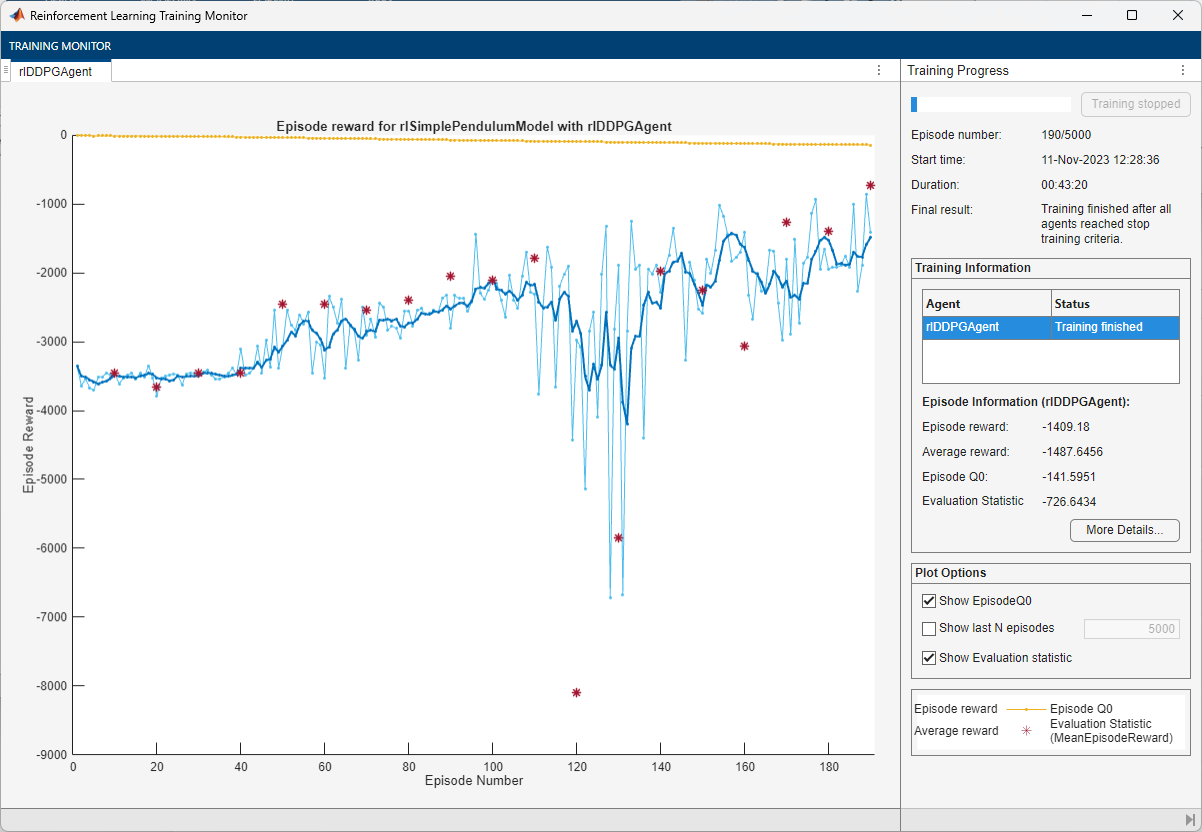

## Simulate DDPG Agent

To validate the performance of the trained agent, simulate it within the pendulum environment. For more information on agent simulation, see [`rlSimulationOptions`](docid:rl_ref#mw_983bb2e9-0115-4548-8daa-687037e090b2) and [`sim`](docid:rl_ref#mw_e6296379-23b5-4819-a13b-210681e153bf).

simOptions = rlSimulationOptions(MaxSteps=500);
experience = sim(env,agent,simOptions);

*Copyright 2019-2022 The MathWorks, Inc.*